## Teoría de Inventarios

f(x): Densidad de la demanda x durante LT (tiempo de entrega del proveedor). (I <= x <= S). Ésta tiene asociada las bien conocidas E(x) y F(x). 

D: Valor esperado de la demanda en el horizonte de planeación. 

Co: Costo de poner una orden. 

Ch: Costo de mantener una unidad del producto por unidad de tiempo. 

p: Costo por no tener una unidad en inventario.


$$\textrm{CT}\left(Q,r\right)=\frac{\textrm{Co}*D}{Q}+\textrm{Ch}*\left(\frac{Q}{2}+r-E\left(x\right)\right)+\left(\frac{p*D}{Q}\right)*\int_r^s \left(x-r\right)f\left(f\right)\textrm{dx}$$


syms x r Q s
a=0;
b=100;
fx= @(x) 1/(b-a)

fx = function_handle with value:
    @(x)1/(b-a)


Ex = double(int(x*fx, a, b))

Ex = 50

Fx = matlabFunction(int(fx, 0, x))

Fx = function_handle with value:
    @(x)x./1.0e+2


D = 1000

D = 1000

Co = 100

Co = 100

Ch= 2

Ch = 2

p = 100

p = 100

z = matlabFunction(int((x-r)*fx(x), r, b))

z = function_handle with value:
    @(r)(r-1.0e+2).^2./2.0e+2


CT = @(Q,r)  Co.*D./Q + Ch.*(Q./2+r-Ex) + (p*D./Q).*z(r)

CT = function_handle with value:
    @(Q,r)Co.*D./Q+Ch.*(Q./2+r-Ex)+(p*D./Q).*z(r)


CTparopt = @(x)  Co.*D./x(1) + Ch.*(x(1)./2+x(2)-Ex) + (p*D./x(1)).*z(x(2))

CTparopt = function_handle with value:
    @(x)Co.*D./x(1)+Ch.*(x(1)./2+x(2)-Ex)+(p*D./x(1)).*z(x(2))


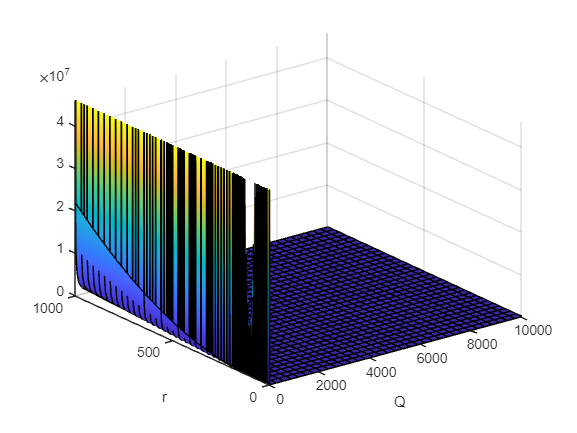

fsurf(CT, [0 10000 0 1000])
xlabel Q
ylabel r

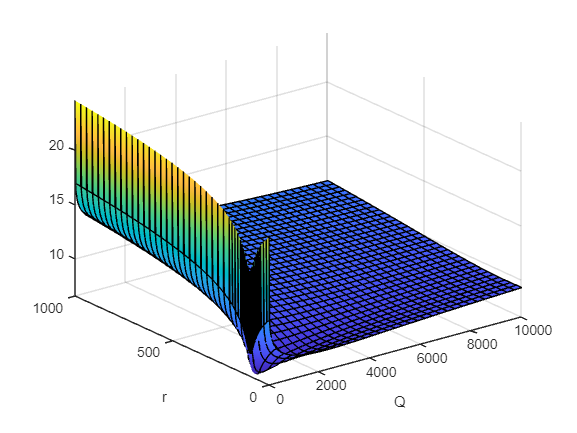

logCT = @(Q,r) log(CT(Q,r));
fsurf(logCT,[0 10000 0 1000])
xlabel Q
ylabel r

x0 = [300, 100]

x0 =    300   100


[QR, fObj]= fminunc(CTparopt,x0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


QR =   316.5445   99.3669


fObj = 731.8228

QOpt = QR(1);
rOpt = QR(2);
CTOpt = CTparopt(QR)

CTOpt = 731.8228

ans2 = [319.44, 93.61];
CTOpt = CTparopt(ans2)

CTOpt = 783.6198

ans2 = [400, 100];
CTOpt = CTparopt(ans2)

CTOpt = 750